clear;
clc;

addpath("util/")

N = 128;              % FOV    
ny = N; nx = N; nz = N;
nc = 4;
gap = 5;

brain = get_brain_phantom(100);
brain = brain(1:2:end,1:2:end,1:2:end);

nTR = floor(N * N ); 
nTR = 2 * round(nTR / 2); % so it is even, we need this for algebraic method

traj = piccini_phyllotaxis(nTR, 1);
traj = traj(1:nTR/2,:);
traj = cat(1, traj, -traj);
traj = traj2points(traj, N, 2);


traj = permute(traj, [3, 2, 1]);
[ndim, nRO, nTR]=size(traj);
sensMap = coilmap([N,N,N], nc, 64);
coil_image = repmat(brain,1,1,1,nc) .* sensMap;
object_mask = coil_image;
object_mask(object_mask > 0) = 1; 
% volumeViewer(sos(coil_image))
clear sensMap


%% ground_truth
disp("computing ground truth")

computing ground truth


obj = nufft_3d(traj,N,'gpu',2);
data = obj.fNUFT(coil_image);
ground_truth = (obj.iNUFT(data, 0));


%% Noisy SNR ~20 std 85; ~SNR 15 std 150 ; ~SNR 10 std 260 ; ~SNR 5 std = 500
std = 260;
disp("computing noisy realisation")

computing noisy realisation


noise = gaussian_noise(size(data),0, std); 
noisy_data = data + noise;                                                                                                                          
% SNR = snr(abs(ground_truth), obj.iNUFT(noise, 0));
noisy_images = (obj.iNUFT(noisy_data, 0));
l2_noisy = l2(noisy_images.*object_mask , ground_truth.*object_mask)

l2_noisy = 97.9556


%% zero_filled
disp("computing zero filled")

computing zero filled


unfilled_zte_data = reshape(noisy_data, nRO, nTR, nc);
obj.nTR = nTR;
obj.nRO = nRO;
obj.gap = gap;
unfilled_zte_data(1:gap,:,:) = 0;
zero_filled = (obj.iNUFT(unfilled_zte_data, 0));
l2_zero_filled =l2(zero_filled.*object_mask , ground_truth.*object_mask)

l2_zero_filled = 1.3226e+03


%% algebraic reconstruction
disp("computing algebraic reconstruction")

computing algebraic reconstruction


algebraic_filled_zte_data = algebraic_method(gather(unfilled_zte_data), gap, nRO, nTR); 
algebraic_recon = (obj.iNUFT(algebraic_filled_zte_data, 0));
l2_algebraic =l2(algebraic_recon.*object_mask, ground_truth.*object_mask)

l2_algebraic = 1.4763e+03


%% zinfandel reconstruction
disp("computing zinfandel recon")

computing zinfandel recon


nk = 5;
nl = 16;
ns = 5;
zinfandel_filled_zte_data = zinfandel_recon(gather(unfilled_zte_data), traj, gap, nk, nl, ns);
zfd_recon = (obj.iNUFT(zinfandel_filled_zte_data, 0));
l2_zfd_recon =l2(zfd_recon, ground_truth)

l2_zfd_recon = 668.0689

%% low rank reconstruction
disp("computing low rank recon")

computing low rank recon


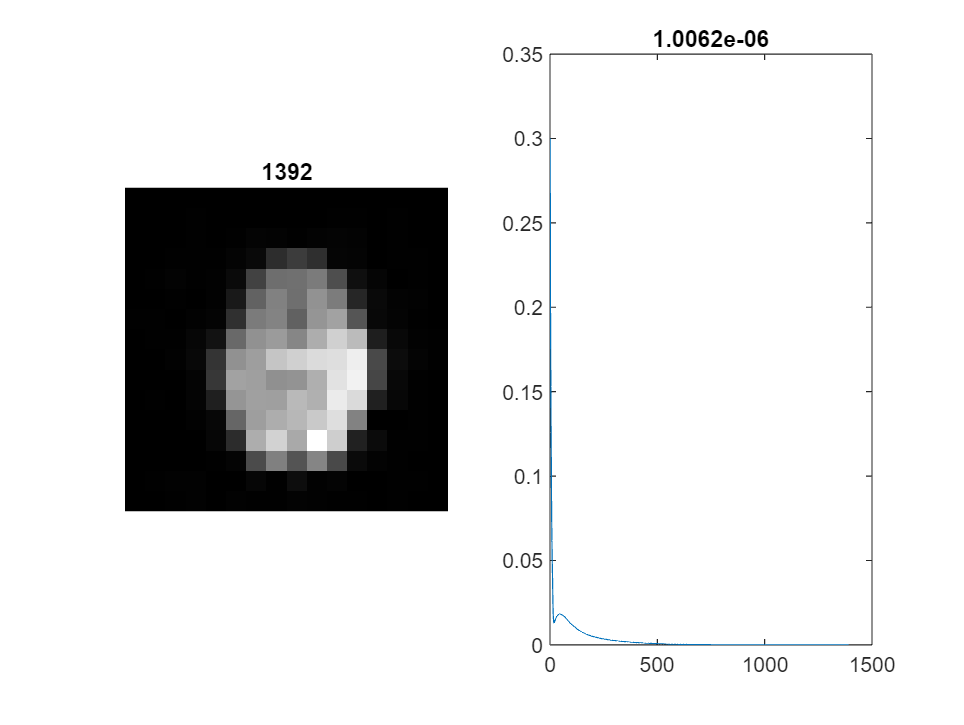

% optional: i suggest to initialise to cg sense (likely suboptimal), 
% otherwise very slow convergence (hours for large gaps)

rank = 85;
fovratio = 8; % normally 6, 8 for slightly faster computation
maxiter = 1500;
lr_filled_zte_data = lowrank_method(unfilled_zte_data, traj, gap, rank, fovratio,maxiter);

lowrank_recon = (obj.iNUFT(lr_filled_zte_data, 0));
l2_lowrank =l2(lowrank_recon.*object_mask, ground_truth.*object_mask)

l2_lowrank = 99.4916


%% Result
noisy_images = sos(noisy_images);
zero_filled = sos(zero_filled);
algebraic_recon = sos(algebraic_recon);
zfd_recon = sos(zfd_recon);
lowrank_recon = sos(lowrank_recon);

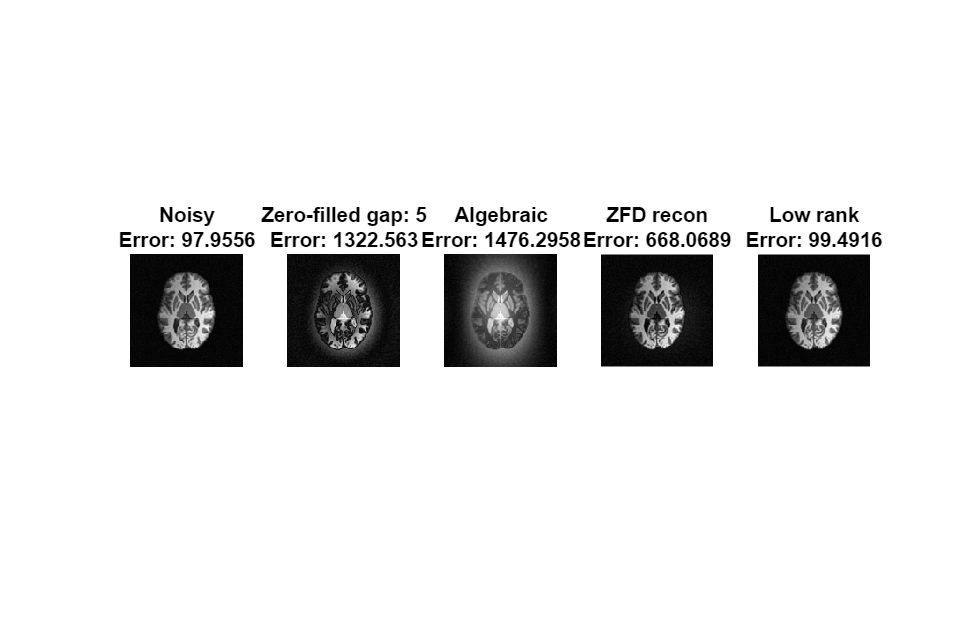


figure(position = [10 10 900 600])
subplot(151)
imshow((noisy_images(:,:,nz/2)),[])
title({"Noisy", "Error: " + string(l2_noisy)})
colormap("gray")

subplot(152)
imshow((zero_filled(:,:,nz/2)),[])
title({"Zero-filled gap: " + string(gap), "Error: " + string(l2_zero_filled)})
colormap("gray")

subplot(153)
imshow((algebraic_recon(:,:,nz/2)),[])
title({"Algebraic", "Error: " + string(l2_algebraic)})
colormap("gray")

subplot(154)
imshow((zfd_recon(:,:,nz/2)),[])
title({"ZFD recon", "Error: " + string(l2_zfd_recon)})
colormap("gray")

subplot(155)
imshow((lowrank_recon (:,:,nz/2)),[])
title({"Low rank", "Error: " + string(l2_lowrank)})
colormap("gray")
saveas(gcf, 'gap_size_3_snr10.jpg')

%% helper functions

function filled_zte_data = lowrank_method(unfilled_zte_data, traj, gap,  rank, fov_ratio, maxiter)
[ndim, nRO, nTR] = size(traj);
N = nRO; 
trim = floor(N/fov_ratio); 
reduced_traj = traj(:,1:trim,:);
[ndim, rnRO, rnTR]=size(reduced_traj);
fov = ceil(max(reduced_traj(:)))*2; 
obj = nufft_3d(reduced_traj,fov,'gpu',2);
lowres_zte_data = unfilled_zte_data(1:trim,:,:);
prev = lowres_zte_data; 
history = [];
k = 5;


for i =1:maxiter
    % textprogressbar(i);
    im3 = obj.iNUFT(lowres_zte_data, 10);
    tmp_data = fft3(im3);
    C = PLOARKS_C(tmp_data, k);
    Cr = rank_approx(C, rank);
    tmp_data = PLOARKS_Cinv(Cr,k, size(tmp_data));
    tmp_image = ifft3(tmp_data);
    tmp_data = obj.fNUFT(tmp_image);
    tmp_data = reshape(tmp_data, rnRO, rnTR,[]);

    tmp_data(gap+1:end,:,:) = lowres_zte_data(gap+1:end,:,:);
    lowres_zte_data = tmp_data;
    
    t = (norm(lowres_zte_data(:)-prev(:))/norm(lowres_zte_data(:))); 
    prev = lowres_zte_data; 
    history = [history t];
    if t < 1e-6
        break
    end
    figure(1)
    subplot(121)
    imshow(sos(im3(:,:,fov/2,:)),[])
    title(string(i))
    subplot(122)
    plot(history)
    title(string(t))
    drawnow()
end
filled_zte_data = unfilled_zte_data;
filled_zte_data(1:gap,:,:) = lowres_zte_data(1:gap,:,:);
end 


% function x = ATA_func(x, sensMap, obj, mask)
%     [ny, nx, nz, nc] = size(sensMap);
%     x = reshape(x, [ny, nx, nz]);
%     coil_image = repmat(x,1,1,1,nc) .* sensMap;
%     data = obj.fNUFT(coil_image);
%     y = data .* mask;
%     coil_image = obj.iNUFT(y, 10);
%     x = sum(coil_image.*conj(sensMap), 4);
%     x = reshape(x, [], 1);
% end
% 
% function x = AT_func(y, sensMap, obj, mask)
%     coil_image = obj.iNUFT(y,0);
%     x = sum(coil_image.*conj(sensMap), 4);
% end


